clc; 
clear;

% definicija funkcije
f = @(lambda) 100 * (1 - (-1 + 4*lambda).^2).^2 + (1 - (-1 + 4*lambda)).^2;

% --- DERIVACIJA f'(lambda) ---
% Računamo analitički po lambdi: x1 = -1 + 4(lambda), x2 = 1
% f = 100*(1 - x1^2)^2 + (1 - x1)^2
% df/d(lambda) = df/dx1 * dx1/d(lambda) = df/dx1 * 4

df_dx1 = @(x1) -400*(1 - x1^2)*x1 - 2*(1 - x1);
df = @(lambda) df_dx1(-1 + 4*lambda) * 4;

% konvergencija
epsilon = 1e-3;

% pocetni interval
A = 0; 
fA = f(A); 
dfA = df(A);
t0 = 0.05; 
B = t0;

while df(B) <= 0
    B = B * 2;
end
fB = f(B); 
dfB = df(B);

fprintf("Početni interval: A = %.5f, B = %.5f\n", A, B);

Početni interval: A = 0.00000, B = 0.05000



% max 2 refita
max_iter = 2;
for iter = 1:max_iter
    % 2. korak: izracunaj Z, Q, lambda*
    Z = 3 * (fA - fB)/(B - A) + dfA + dfB;
    Q = sqrt(Z^2 - dfA * dfB);
    lambda_star = B - ((B - A) * (dfB + Q - Z)) / (dfB - dfA + 2*Q);

    f_star = f(lambda_star);
    df_star = df(lambda_star);
    
    fprintf("Iteracija %d:\n", iter);
    fprintf("lambda = %.6f, f(lambda) = %.6f, f'(lambda) = %.6f\n", lambda_star, f_star, df_star);
    
    % Provjera konvergencije
    if abs(df_star) < epsilon
        fprintf("Konvergencija postignuta nakon %d iteracija.\n", iter);
        break;
    end
    
    % Refit – azuriraj A ili B
    if df_star < 0
        A = lambda_star; fA = f_star; dfA = df_star;
    else
        B = lambda_star; fB = f_star; dfB = df_star;
    end
end

Iteracija 1:


lambda = 0.001268, f(lambda) = 3.989976, f'(lambda) = 0.150186


Iteracija 2:


lambda = 0.001256, f(lambda) = 3.989975, f'(lambda) = -0.000001


Konvergencija postignuta nakon 2 iteracija.



% rezultat
X_min = [-1 + 4*lambda_star; 1];
fprintf("\nMINIMUM NA:\nlambda(minimum funkcije) = %.6f\nX = [%.6f; %.6f]\nf(X) = %.6f\n", ...
    lambda_star, X_min(1), X_min(2), f(lambda_star));


MINIMUM NA:
lambda(minimum funkcije) = 0.001256
X = [-0.994975; 1.000000]
f(X) = 3.989975


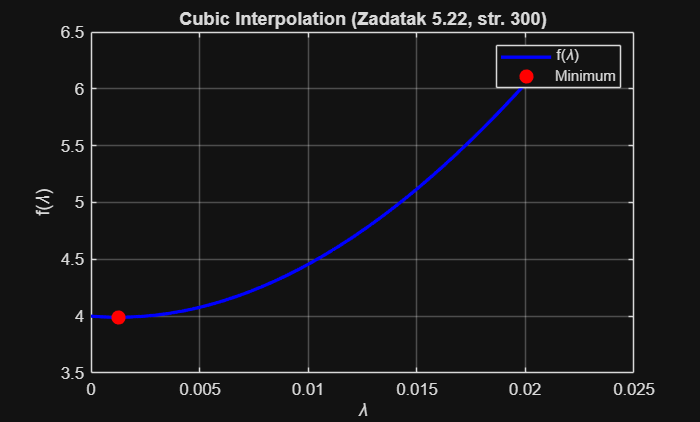


% plotanje
lambda_vals = linspace(0, B + 0.02, 500);
plot(lambda_vals, f(lambda_vals), 'b-', 'LineWidth', 2); hold on;
plot(lambda_star, f(lambda_star), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
xlabel('\lambda'); ylabel('f(\lambda)');
title('Cubic Interpolation (Zadatak 5.22, str. 300)');
grid on;
legend('f(\lambda)', 'Minimum');